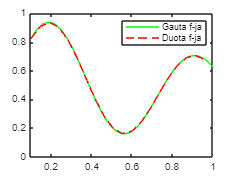

close all

x= 0.1:1/22:1;
% Naudojama funkcija
target_function = ((1 + 0.6*sin(2*pi*x/0.7)) + 0.3*sin(2*pi*x))/2;


% iėjimo slouksniu koficientai
w11_1 = rand(1); b1_1 = rand(1);
w21_1 = rand(1); b2_1 = rand(1);
w31_1 = rand(1); b3_1 = rand(1);
w41_1 = rand(1); b4_1 = rand(1);
w51_1 = rand(1); b5_1 = rand(1);
w61_1 = rand(1); b6_1 = rand(1);

% isejimo sluoksnio koficientai
w11_2 = rand(1); 
w12_2 = rand(1);
w13_2 = rand(1);
w14_2 = rand(1);
w15_2 = rand(1);
w16_2 = rand(1);

b1_2 = rand(1);

% mokymo zingsnis
eta = 0.1;

for n=1:1000000
    for i=1:20
        % I sluoksnio įėjimai
        v1_1 = w11_1*x(i)+b1_1;
        v2_1 = w21_1*x(i)+b2_1;
        v3_1 = w31_1*x(i)+b3_1;
        v4_1 = w41_1*x(i)+b4_1;
        v5_1 = w51_1*x(i)+b5_1;
        v6_1 = w61_1*x(i)+b6_1;

        % isejimas is pirmojo sluoksnio
        y1_1 = 1/(1+exp(-v1_1));
        y2_1 = 1/(1+exp(-v2_1));
        y3_1 = 1/(1+exp(-v3_1));
        y4_1 = 1/(1+exp(-v4_1));
        y5_1 = 1/(1+exp(-v5_1));
        y6_1 = 1/(1+exp(-v6_1));

        % Neurono isejimas
        yout = w11_2*y1_1 + w12_2*y2_1 + w13_2*y3_1 + w14_2*y4_1 + w15_2*y5_1 + w16_2*y6_1 + b1_2;

        
        % nuokrypis nuo norimos funkcijos
        delta_out=target_function(i) - yout;
        
        % isejimo neurono koeficientu keitimas
        w11_2 = w11_2 + eta * delta_out * y1_1;
        w12_2 = w12_2 + eta * delta_out * y2_1;
        w13_2 = w13_2 + eta * delta_out * y3_1;
        w14_2 = w14_2 + eta * delta_out * y4_1;
        w15_2 = w15_2 + eta * delta_out * y5_1;
        w16_2 = w16_2 + eta * delta_out * y6_1;
        b1_2 = b1_2 + eta * delta_out;

        % II sluoksnio neuronu nuokrypiai (gradientai)
        delta1_1= y1_1 * (1-y1_1) * delta_out * w11_2;
        delta2_1= y2_1 * (1-y2_1) * delta_out * w12_2;
        delta3_1= y3_1 * (1-y3_1) * delta_out * w13_2;
        delta4_1= y4_1 * (1-y4_1) * delta_out * w14_2;
        delta5_1= y5_1 * (1-y5_1) * delta_out * w15_2;
        delta6_1= y6_1 * (1-y6_1) * delta_out * w16_2;
        
        % II sluoksnio neuronu koeficientu svorio keitimas
        w11_1 = w11_1 + eta * delta1_1 * x(i);
        w21_1 = w21_1 + eta * delta2_1 * x(i);
        w31_1 = w31_1 + eta * delta3_1 * x(i);
        w41_1 = w41_1 + eta * delta4_1 * x(i);
        w51_1 = w51_1 + eta * delta5_1 * x(i);
        w61_1 = w61_1 + eta * delta6_1 * x(i);
        
        % pasleptu neuronu koeficientu poslinkio keitimas
        b1_1= b1_1 + eta * delta1_1;
        b2_1= b2_1 + eta * delta2_1;
        b3_1= b3_1 + eta * delta3_1;
        b4_1= b4_1 + eta * delta4_1;
        b5_1= b5_1 + eta * delta5_1;
        b6_1= b6_1 + eta * delta6_1;
    end
end


test_X = linspace(0.1, 1, 200);
% testavimas
for m = 1:200
    v1_1 = test_X(m)*w11_1 + b1_1;
    v2_1 = test_X(m)*w21_1 + b2_1;
    v3_1 = test_X(m)*w31_1 + b3_1;
    v4_1 = test_X(m)*w41_1 + b4_1;
    v5_1 = test_X(m)*w51_1 + b5_1;
    v6_1 = test_X(m)*w61_1 + b6_1;

    y1_1 = 1/(1+exp(-v1_1));
    y2_1 = 1/(1+exp(-v2_1));
    y3_1 = 1/(1+exp(-v3_1));
    y4_1 = 1/(1+exp(-v4_1));
    y5_1 = 1/(1+exp(-v5_1));
    y6_1 = 1/(1+exp(-v6_1));

    v1_2 = w11_2*y1_1 + w12_2*y2_1 + w13_2*y3_1 + w14_2*y4_1 + w15_2*y5_1 + w16_2*y6_1 + b1_2;

    yout_Final(m) = v1_2;
end

figure
plot(test_X,yout_Final,'g', x, target_function, 'r--')
legend('Gauta f-ja','Duota f-ja')
xlim([0.1 1])